# Examples of how to use `mexPD_2d` and `mexPDall_2d` to generate Laguerre diagrams

First we recall the definition of a Laguerre diagram. Let $\Omega \subset \mathbb{R}^2$ be the rectangle $\Omega = [X_{\mathrm{min}},X__{\mathrm{max}}]\times[Y_{\mathrm{min}},Y_{\mathrm{max}}]$. Given **seeds** $x_1,x_2,\ldots,x_N$, with $x_i \in \mathbb{R}^2$, and **weights** $w_1,w_2,\ldots,w_N$, with $w_i \in \mathbb{R}$, the **Laguerre tessellation** of $\Omega$ generated by the seeds and weights is the collection of convex polygons $L_1,L_2,\ldots,L_N$ defined by 


$$L_i = \left\{ x \in \Omega : \| x-x_i \|^2-w_i \le \| x -x_j \|^2-w_j \; \forall \, j \in \{1,\ldots,N\} \right\}.$$


The convex polygons $L_i$ are called **Laguerre cells**.

In these examples we show how to compute Laguerre cells and their properties (e.g., areas, centroids, vertices, neighbours) using `mexPD_2d` and `mexPDall_2d`. We also show how to plot Laguerre tessellations using `plot_cells2d` (see Section 2.3).

## 1. Example of `mexPD_2d`

First we give an example of how to generate a Laguerre diagram in the rectangle $[0,1]\times[0,2]$. We define the box (the domain $\Omega$) as follows:

bx=[0,0,1,2];   % The domain specified as [xmin,ymin,xmax,ymax]
l1=bx(3)-bx(1); % l1=xmax-xmin
l2=bx(4)-bx(2); % l2=ymax-ymin

 Next we define the generators of the Laguerre diagram. We take $N$ seeds whose positions are uniformly distributed in the domain $[0,1]\times[0,2]$.

N=100; % The number of seeds
x=[bx(1) bx(2)]+rand(N,2)*diag([l1,l2]); % Coords of seeds, randomly located in the box

Note that the seeds can lie outside $\Omega$.

We also choose the weights of the generators at random. Note that when all the weights are zero we have the standard **Voronoi** diagram.

w=rand(N,1)/50; % Weights of the generators, N-by-1 array

Finally, we set the periodicity in both the x and y directions to false. Note that the periodicity in each direction can be controlled separately.

periodic_x=false; % Periodicity in the x-direction
periodic_y=false; % Periodicity in the y-direction

We compute the Laguerre diagram as follows:

[v,t,xc]=mexPD_2d(bx,x,w,periodic_x,periodic_y); % PD stands for 'Power Diagram'

Here `v` is a vector of length $N$ (size $100\times 1$ in this example) containing the **areas** of the Laguerre cells, e.g., `v(23)` is the area of cell 23. Let's check that the areas of the Laguerre cells add up to the area of the box: 

sum(v)-l1*l2 % this should be zero

ans = 0

In a Laguerre diagram some of the cells may be empty. Let's compute how many cells have zero area:

num_empty_cells=length(find(v==0)) % number of empty cells in the Laguerre diagram

num_empty_cells = 8

The return argument `xc` (see line 7) is an array of size $100 \times 2$ containing the coordinates of the **centroids** of the cells, e.g., the centroid of cell 1 is

k=1; % cell index
centroid_cell_1=xc(k,:) % coordinates of the centroid of cell k

centroid_cell_1 =     0.8736    0.3884


Note: If a cell is empty, then mexPD defines its centroid to be `[0,0]`.

The return argument `t `(see line 9) contains the **second moments** of the Laguerre cells about the seeds. For example, `t(1)` equals 


$$\int_{L_1} \| x-x_1 \|^2 \, dx.$$
  

This is useful for applications in **optimal transport theory**. In particular, `sum(t)` equals the cost of transporting the Lebesgue measure on $\Omega$ to the discrete measure $\sum_{k=1}^N |L_k| \delta_{x_k}$with respect to the quadratic transport cost, where $|L_k|$ equals the volume of cell $k$. In other words, `sum(t)` equals the squared Wasserstein distance


$$W_2^2 \left( 1, \sum_{k=1}^N |L_k| \delta_{x_k} \right) = \sum_{k=1}^N \int_{L_k} \| x - x_k \|^2 \, dx.$$


transport_cost=sum(t) % Gives the total transport cost above

transport_cost = 0.0152

Important: `mexPD_2d` does **not** return the vertices of the Laguerre cells or the neighbour relations. To compute these use `mexPDall_2d` (see Example 2 below). For Laguerre diagrams with many seeds, `mexPD_2d` is usually the quickest option if you need the basic properties of the Laguerre cells but not the cells themselves.

### 1.1. Periodic Laguerre diagrams

Now we give an example of how to generate a **periodic** Laguerre diagram. First we recall the definition. Let $\Omega \subset \mathbb{R}^2$ be a rectangle $\Omega = [X_{\mathrm{min}},X_{\mathrm{max}}]\times[Y_{\mathrm{min}},Y_{\mathrm{max}}]$. Given **seeds** $x_1,x_2,\ldots,x_N$, with $x_i\in\mathbb{R}^2$, and **weights** $w_1,w_2,\ldots,w_N$, with $w_i \in \mathbb{R}$, the **periodic** **Laguerre tessellation** of $\Omega$ generated by the seeds and weights is the collection of sets $L_1^{\mathrm{per}},L_2^{\mathrm{per}},\ldots,L_N^{\mathrm{per}}$ defined by 


$$L_i^{\mathrm{per}} = \left\{ x \in \Omega : \| x-x_i \|_{\mathrm{per}}^2-w_i \le \| x -x_j \|_{\mathrm{per}}^2-w_j \; \forall \, j \in \{1,\ldots,N\} \right\}$$


where $\| x-x_i \|_{\mathrm{per}}$ is the periodic distance between $x$ and $x_i$. The periodicity can be in both directions (parallel to the sides of the box) or in only one direction, or neither direction. For example if the periodicity is only in the $x$-direction (flat cylinder) then the periodic distance is


$$\| x-x_i \|_{\mathrm{per}} = \min_{k_1\in \mathbb{Z}} \| x - x_i - (k_1 l_1,0)\|,$$


where $l_1=X_{\mathrm{max}}-X_{\mathrm{min}}$ (the horizontal period). If the periodicity is only in the $y$-direction then the periodic distance is


$$\| x-x_i \|_{\mathrm{per}} = \min_{k_2\in \mathbb{Z}} \| x - x_i - (0,k_2 l_2)\|,$$


where $l_2=Y_{\mathrm{max}}-Y_{\mathrm{min}}$ (the vertical period). If the periodicity is in both directions (flat torus) then the periodic distance is


$$\| x-x_i \|_{\mathrm{per}} = \min_{k\in \mathbb{Z}^2} \| x - x_i - (k_1l_1,k_2 l_2)\|.$$


The following code generates a periodic (in both directions) Laguerre diagram in the unit square $[0,1]\times[0,1]$ with $N=10,000$ randomly located seeds and random weights:

bx=[0,0,1,1];   % The domain is [0,1]x[0,1]
l1=bx(3)-bx(1); % The horizontal period l1
l2=bx(4)-bx(2); % The vertical period l2
N=10000; % number of seeds
X=[bx(1),bx(2)]+rand(N,2)*diag([l1,l2]); % coords of the seeds, randomly located in the box bx 
w=rand(N,1)/1000; % weights of the Laguerre diagram
periodic=true;    % set periodic=true to generate a periodic Laguerre diagram
tic;
[v,t,xc]=mexPD_2d(bx,X,w,periodic); % generate the Laguerre diagram
toc

Elapsed time is 0.090534 seconds.


In the next example we specify periodicity in the y-direction, but not the x-direction.

bx=[0,0,1,2]; % The domain is [0,1]x[0,2]
l1=bx(3)-bx(1); % The horizontal width l1
l2=bx(4)-bx(2); % The vertical period l2
N=1000; % number of seeds
X=[bx(1) bx(2)]+rand(N,2)*diag([l1,l2]); % coords of the seeds, randomly located in the domain
w=2*rand(N,1)/N; % random weights
periodic_x=false; % Not periodic in the x-direction
periodic_y=true;  % Periodic in the y-direction
tic
[v,t,xc]=mexPD_2d(bx,X,w,periodic_x,periodic_y);
toc

Elapsed time is 0.017869 seconds.


### 1.2. Centroids

The centroid of a periodic Laguerre cell is defined to be the centroid of the corresponding non-periodic Laguerre cell in the Laguerre tessellation of $\mathbb{R}^2$ generated by appropriate periodic copies of the seeds: 


$$\bar{x}_i=\frac{1}{|\tilde{L}_i|} \int_{\tilde{L}_i} x \, dx$$


where $\tilde{L}_i$ is the non-periodic Laguerre cell, and $|\tilde{L}_i|$ is the area of $\tilde{L_i}$, which equals the area of $L_i^{\mathrm{per}}$. For further details see `Examples3d`.

Similarly, the transport cost of a periodic Laguerre cell is defined by


$$\int_{\tilde{L}_i} \| x - x_i \|^2 \, dx.
$$


The centroids and transport costs are returned in the arguments `xc` and `t.`

### 1.3. Special case: Voronoi diagrams

A Voronoi diagram is a special type of Laguerre diagram where all the weights are equal: $w_1=w_2=\cdots=w_N$. Without loss of generality we can choose the weights to be zero. In the following example we create a non-periodic Voronoi diagram with $N=2^{2n}$ cells forming a $2^n\times2^n$ square pixelation of the unit square $[0,1]\times[0,1]$:  

bx=[0,0,1,1]; % Omega is [0,1]x[0,1]
n=1;h=1/(2^n);x=-h/2+h*(1:(2^n)); 
[X1,X2]=meshgrid(x,x);
X1=reshape(X1,2^(2*n),1);
X2=reshape(X2,2^(2*n),1);
X=[X1,X2]; % coords of the seeds, arranged in a 2D checkerboard pattern - dimension 2^{2n}-by-2
w=zeros(2^(2*n),1); % set the weights to be zero to generate a Voronoi diagram
periodic=false; % not periodic
[v,t,xc]=mexPD_2d(bx,X,w,periodic); % generate the Voronoi diagram

The Voronoi cells all have volume $2^{-2n}$:

disp(v)

    0.2500
    0.2500
    0.2500
    0.2500



 The centroids `xc` of the Voronoi cells are the same as the seed locations `X` (ie the Voronoi diagram is a **Centroidal Voronoi Tessellation**). We can check this by computing the different between `X` and `xc`.

disp(X-xc)

     0     0
     0     0
     0     0
     0     0



### 1.4. Optional arguments

The standard way of calling `mexPD_2d` is `[v,t,xc]=mexPD_2d(bx,X,w,periodic_x,periodic_y)`. However, the arguments `bx`, `w` and `periodic_x and periodic_y` are optional. If they are not specified, then they take the default values 

- `bx=[0,0,1,1]`  (unit square)

- `w=zeros(size(X,1),1) `(Voronoi diagram) 

- `periodic_x=false`

- `periodic_y=false`

For example, we can repeat the previous example of a non-periodic Voronoi diagram in the unit square as follows:

[v,t,xc]=mexPD_2d(X); % generate the Voronoi diagram
disp(v)

    0.2500
    0.2500
    0.2500
    0.2500



## 2. Example of mexPDall_2d

The function `mexPDall_2d` has an additional return argument `vfn`: 

`[v,t,xc,vfn]=mexPDall_2d(box,x,w,periodic_x,periodic_y)`

The cell array `vfn` contains information about the **v**ertices, **f**aces, and **n**eighbours of the Laguerre cells, and is useful for plotting the Laguerre tessellation. Here is an example:

bx=[0,0,1,1]; % Domain is [0,1]x[0,1]
N=100;        % Number of seeds
X=rand(N,2);  % Random locations of seeds within Omega
w=rand(N,1)/1000; % Random weights
periodic=false; % Non-periodic case
[v,t,xc,vfn]=mexPDall_2d(bx,X,w,periodic); 

`vfn` is a cell array of size $N\times2$. 

### **2.1. First column of **`vfn`**: vertices**

The coordinates of the vertices of the $i$-th Laguerre cell are stored in `vfn{i,1}`. They are ordered anti-clockwise around the cell.

i=53; % cell index
vertices_cell_i=vfn{i,1} % coordinates of the vertices of cell i

vertices_cell_i =     0.1923    0.5378
    0.2660    0.5539
    0.2685    0.6018
    0.2561    0.6299
    0.2315    0.6666
    0.2252    0.6686
    0.1556    0.6095


If the $i$-th Laguerre cell has `Nv` vertices, then `vfn{i,1}` is an array of size `Nv x 2.` The $k$-th vertex of the $i$-th cell has coordinates `vfn{i,1}(k,:)`:

Nv=size(vfn{i,1},1) % number of vertices of cell i

Nv = 7

vfn{i,1}(1,:) % coordinates of the 1st vertex of cell i

ans =     0.1923    0.5378


The faces (edges) of the cell are line segments consisting of consecutive pairs of vertices. The $j$-th edge has vertices $v_j$ and $v_{j+1}$ (where $v_{N_v+1}=v_1$).

### **2.2. Second column of **`vfn`**: neighbours **

If the $i$-th Laguerre cell has `Nv` vertices then it has `Nv` edges, and `vfn{i,2}` is an `Nvx`1 integer array containing the indices of the neighbours of cell $i$.

number_edges=length(vfn{i,2}) % number of edges of cell i

number_edges = 7

neighbours_cell_i=vfn{i,2}' % indices of the neighbours of cell i

neighbours_cell_i = 1×7 int32 row vector
   79    3    5   44    2   70   85


In other words, if the array `vfn{i,2}` contains the index `k`, then cells $L_i$ and $L_k$ are neighbours (share an edge). If `vfn{i,2}(j)` is negative, then the $j$-th edge of the $i$-th cell lies on the boundary of the box `bx`.

Here is a quick consistency check:

i=4; % cell index
neighbours_cell_i=sort(vfn{i,2}); % neighbour indices of cell i, sorted in increasing order
k=neighbours_cell_i(end) % neighbour of cell i with the largest index

k = int32
88

neighbours_cell_k=sort(vfn{k,2})' % neighbour indices of cell i

neighbours_cell_k = 1×5 int32 row vector
   -96     4    21    51    86


ismember(i,neighbours_cell_k) % check that i is a neighbour of k - should return logical 1

ans = logical
   1


### 2.3. Plotting Laguerre tessellations using `plot_cells2d`

In this example we show how to plot Laguerre tessellations and individual Laguerre cells. First we generate a Laguerre tessellation using `mexPDall_2d.`

bx=[0,0,3,4];   % Omega is [0,3]x[0,4]
l1=bx(3)-bx(1); % x-Length of Omega
l2=bx(4)-bx(2); % y-Length of Omega
N=25; % number of seeds
X=[bx(1) bx(2)]+rand(N,2)*diag([l1 l2]); % coords of the seeds, randomly located in the box bx
w=rand(N,1)/25; % weights of the Laguerre diagram
periodic=false; 
[~,~,~,vfn]=mexPDall_2d(bx,X,w,periodic);

The cell array `vfn` is used by `plot_cells2d` to plot the Laguerre tessellation:

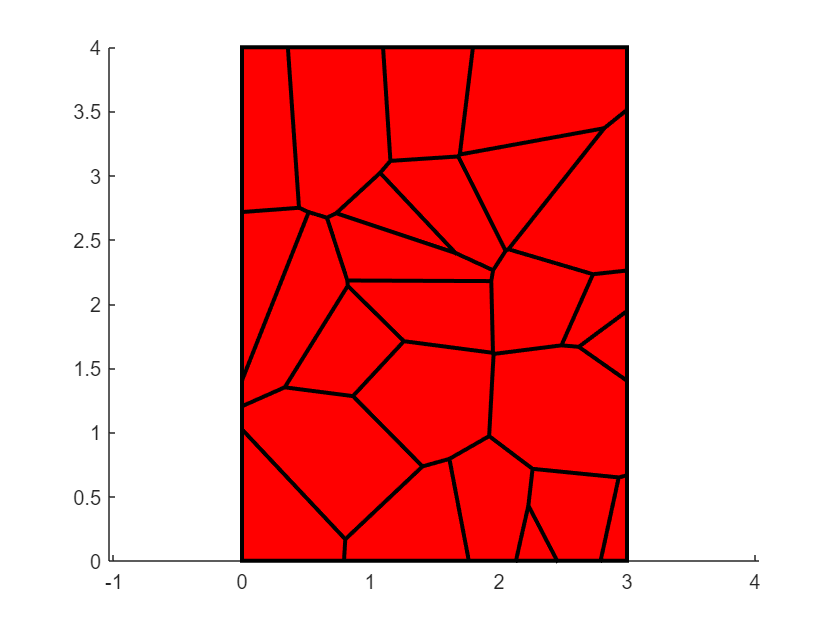

figure
plot_cells2d(vfn);
xlim([bx(1) bx(3)]);ylim([bx(2) bx(4)]);axis equal

The function `plot_cells2d` has two optional arguments to allow you to choose which cells to plot and how to colour them:

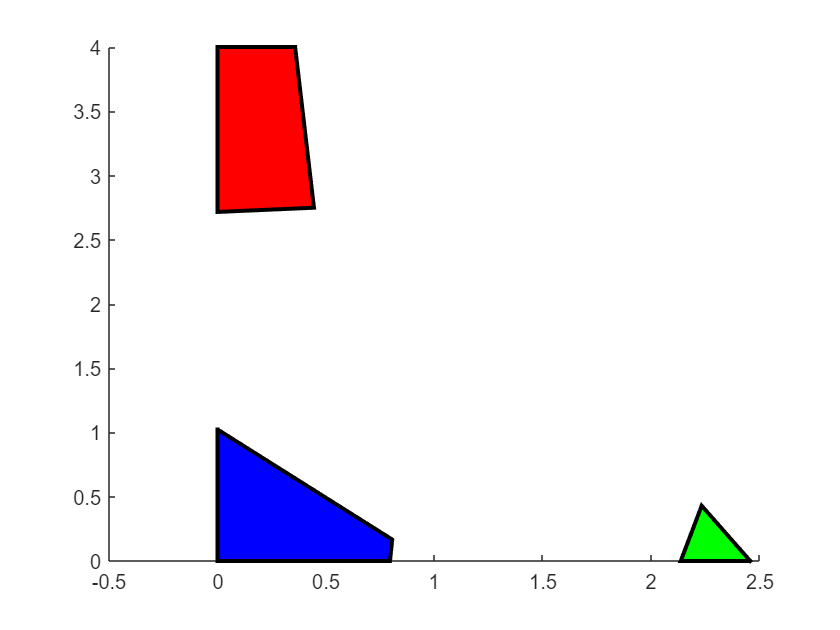

figure
plot_cells2d(vfn,[1;5;19],['r';'g';'b']); % Plot cells 1, 5, 19, colour them red, green, blue

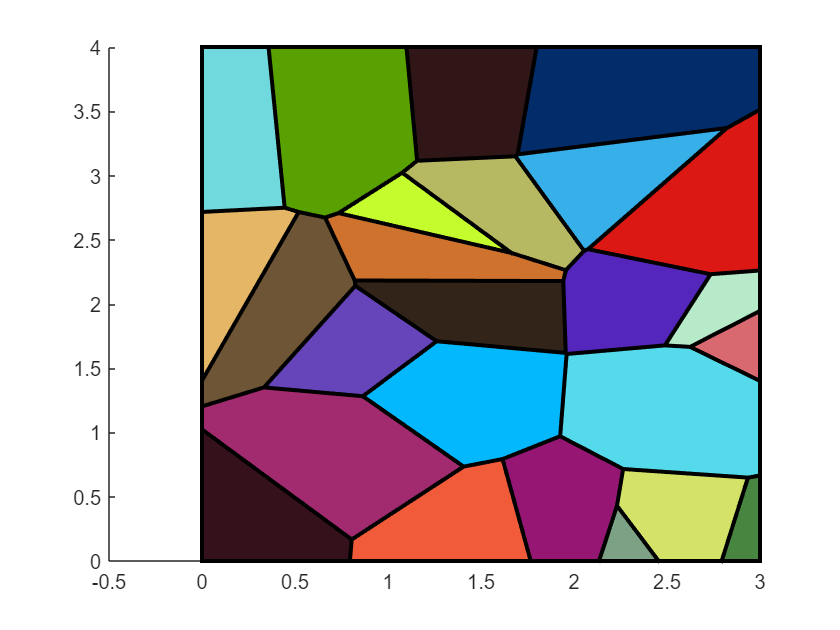

figure
plot_cells2d(vfn,[1:N]',rand(N,3)); % Plot all the cells in randomly chosen colours

For **periodic** Laguerre diagrams, the function `plot_cells` plots the cells $\tilde{L}_i$ defined above in Section 1.1 rather than the periodic cells $L_i^{\mathrm{per}}$:

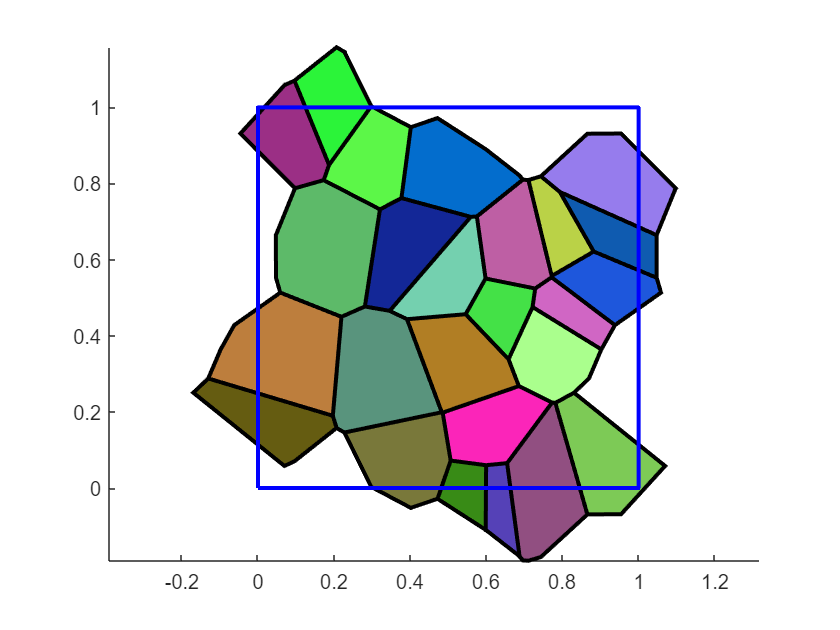

N=25;         % Number of cells
bx=[0,0,1,1]; % Omega is [0,1]x[0,1]

% Make the vertices of the domain, for plotting
bbx=[bx(1) bx(2);
    bx(3) bx(2);
    bx(3) bx(4);
    bx(1) bx(4);
    bx(1) bx(2);];

X=[bx(1) bx(2)]+rand(N,2)*diag([bx(3)-bx(1),bx(4)-bx(2)]);  % Random seed locations
[~,~,~,vfn]=mexPDall_2d(bx,X,true); % w takes default value, w=zeros(N,1)

% Make the figure

figure;
clf;
plot_cells2d(vfn,[1:N]',rand(N,3));
hold on
plot(bbx(:,1),bbx(:,2),'b','LineWidth',2); % Plot the boundary of Omega
hold off
axis equal

In the next example we specify that the diagram is periodic in the y-direction but not the x-direction. Notice that sometimes the seeds lie outside their corresponding cells, which is a generic feature of Laguerre diagrams (unlike Voronoi diagrams in which the seed always lies inside its corresponding cell and the cell is non-empty.

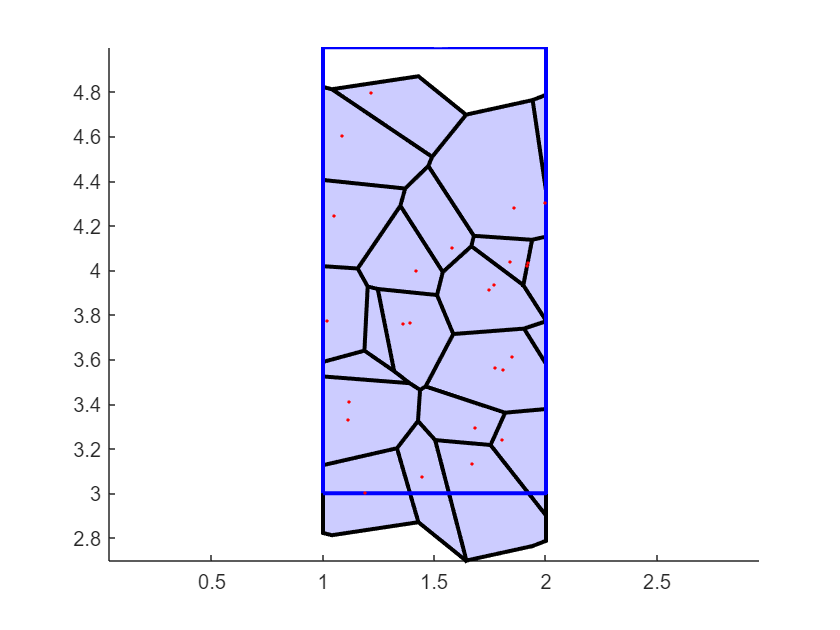

N=25;         % Number of seeds
bx=[1,3,2,5]; % Omega is [1,2]x[3,5]

% Make the vertices of the domain, for plotting
bbx=[bx(1) bx(2);
    bx(3) bx(2);
    bx(3) bx(4);
    bx(1) bx(4);
    bx(1) bx(2);];

X=[bx(1) bx(2)]+rand(N,2)*diag([bx(3)-bx(1),bx(4)-bx(2)]);   % Random seed locations
w=rand(N,1)/N; % Random weights
[~,~,~,vfn]=mexPDall_2d(bx,X,w,false,true); % periodic in the y-direction

% Make the figure

lightblue=[0.8 0.8 1];
figure;
clf;
plot_cells2d(vfn,[1:N]',lightblue);
hold on
plot(bbx(:,1),bbx(:,2),'b','LineWidth',2); % Plot the boundary of Omega
plot(X(:,1),X(:,2),'r.','Markersize',5); % Plot the seed locations
hold off
axis equal

In the next example we illustrate that the seeds can lie outside the domain. The notion of outside only makes sense in non-periodic cases. In the example, all the seeds but one lie outside the domain.

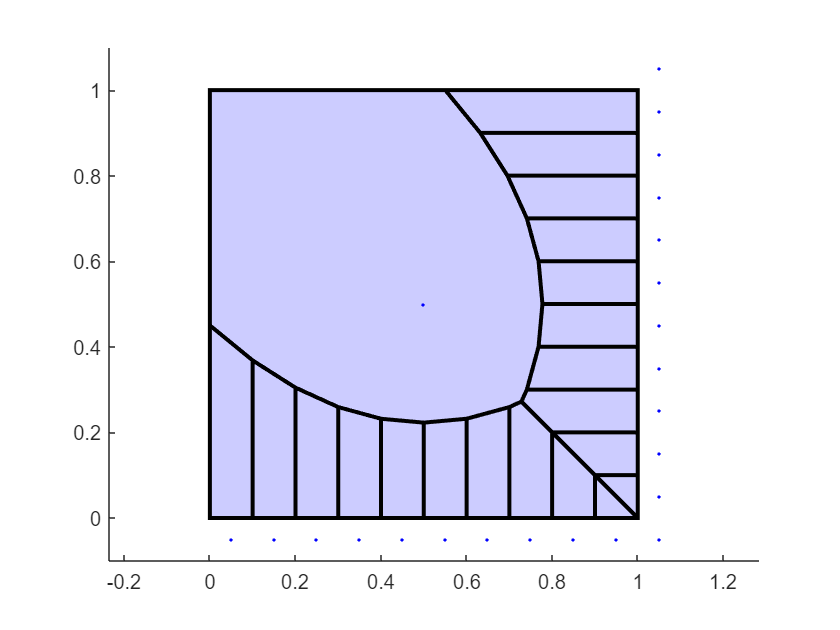

bx=[0,0,1,1]; % Unit square
n=10;h=1/n;
s=h*(-0.5+1:11)';
X=[s,-h/2*ones(n+1,1);
    (1+h/2)*ones(n+1,1),s;
    0.5,0.5];
[~,~,~,vfn]=mexPDall_2d(bx,X); % w takes default value, w=zeros(N,1)

% Make the figure

[N,~]=size(X);
figure;
clf;
plot_cells2d(vfn,[1:N]',lightblue);
hold on
plot(X(:,1),X(:,2),'b.','MarkerSize',5);
hold off
ylim([-h,1+h]);
xlim([-h,1+h]);
axis equal